load("DEV1_Combined_11_17_test_processed.mat")

N1_TPDO0.Properties.RowTimes(1) = '2022-11-17 15:14:26.00'; % reset row times to be equal
N1_TPDO1.Properties.RowTimes(1) = '2022-11-17 15:14:26.00';
N1_TPDO2.Properties.RowTimes(1) = '2022-11-17 15:14:26.00';


Acceleration(1:50,:) = []; % remove rows before the initial timestamp
Acceleration.Properties.RowTimes(1) = '17-Nov-2022 15:14:26.00';  % reset row times to be equal
AngularVelocity(1:50,:) = [];
AngularVelocity.Properties.RowTimes(1) = '17-Nov-2022 15:14:26.00';
Orientation(1:50,:) = [];
Orientation.Properties.RowTimes(1) = '17-Nov-2022 15:14:26.00';
Position(1:4,:) = [];
Position.Properties.RowTimes(1) = '17-Nov-2022 15:14:26.00';


dtMCCan = 1; %ms motor controller message interval
dtMobile = 100; %ms gps time interval 
N1_TPDO0.Properties.VariableNames{2} = 'RPM_actual_value';
Position.speed = Position.speed*2.237; % convert motor controller speed from m/s to mph

Acceleration1 = retime(Acceleration, 'regular','linear','TimeStep',milliseconds(100)); % linear interpolation of the data with 0.1s timestamps.
AngularVelocity1 = retime(AngularVelocity, 'regular','linear','TimeStep',milliseconds(100));
Orientation1 = retime(Orientation, 'regular','linear','TimeStep',milliseconds(100));
Position1 = retime(Position,'regular','linear','TimeStep',milliseconds(100));
N1_TPDO01 = retime(N1_TPDO0, 'regular','linear','TimeStep',milliseconds(100));
N1_TPDO11 = retime(N1_TPDO1, 'regular','linear','TimeStep',milliseconds(100));
N1_TPDO21 = retime(N1_TPDO2, 'regular','linear','TimeStep',milliseconds(100));

Acceleration1.Properties.VariableNames{1} = 'Accel_X'; % rename variables
Acceleration1.Properties.VariableNames{2} = 'Accel_Y';
Acceleration1.Properties.VariableNames{3} = 'Accel_Z';


heights = [height(N1_TPDO01), height(N1_TPDO11), height(N1_TPDO21),height(Acceleration1), height(AngularVelocity1), height(Orientation1), height(Position1)];
minHeight = min(heights) % find the minimum height of the arrays

minHeight = 10477

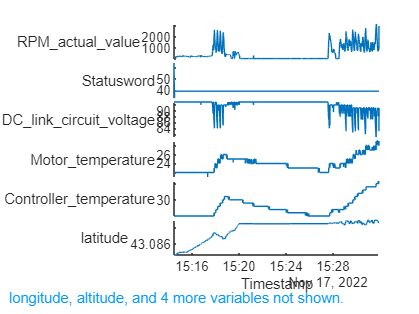


N1_TPDO01(minHeight:end,:) = []; % make all arrays the same length
N1_TPDO11(minHeight:end,:) = [];
N1_TPDO21(minHeight:end,:) = [];
Acceleration1(minHeight:end,:) = [];
AngularVelocity1(minHeight:end,:) = [];
Orientation1(minHeight:end,:) = [];
Position1(minHeight:end,:) = [];

CombinedData = [N1_TPDO01, N1_TPDO11,Position1,Acceleration1]; % horizontally concatenate the timetables

CombinedData = removevars(CombinedData, 'Logic_power_supply_voltage'); %remove useless or redundant variables
CombinedData = removevars(CombinedData, 'Current_demand');
CombinedData = removevars(CombinedData, 'course');
CombinedData = removevars(CombinedData, 'hacc');
CombinedData = removevars(CombinedData, 'Torque_actual_value');
CombinedData.DC_link_circuit_voltage = CombinedData.DC_link_circuit_voltage/10;

stackedplot(CombinedData) % generate a plot of the data

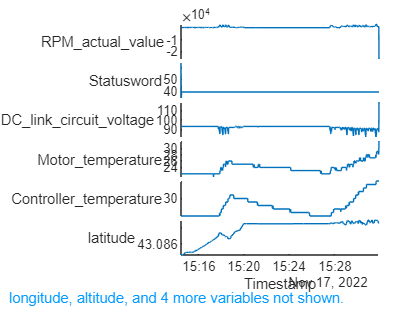


CombinedData1 = retime(CombinedData, 'regular','pchip','TimeStep',seconds(1));

stackedplot(CombinedData1)


% Speed = table2geotable(timetable2table([string(CombinedData.Timestamp), CombinedData.latitude, CombinedData.longitude, CombinedData.speed]))


CBdata = timetable2table(CombinedData);
CBdata1 = timetable2table(CombinedData1);
CBdata1(1:200,:) = []; 
% % convert time to epoch
% convertTo(CBdata.Timestamp,'epochtime','Epoch','1970-01-01','TicksPerSecond',1000);
% CBdata.Timestamp = X

CBdata.Timestamp.Format = "uuuu-MM-dd HH:mm:ss.S"

CBdata = 10476×13 table
          Timestamp          RPM_actual_value    Statusword    DC_link_circuit_voltage    Motor_temperature    Controller_temperature    latitude    longitude    altitude    speed    Accel_X    Accel_Y    Accel_Z
    _____________________    ________________    __________    _______________________    _________________    ______________________    ________    _________    ________    _____    _______    _______    _______

    2022-11-17 15:14:26.0           0                  64                93                      22        


GT = table2geotable(CBdata);
GT.Shape

ans =   10476×1 geopointshape array with properties:

               NumPoints: [10476×1 double]
                Latitude: [10476×1 double]
               Longitude: [10476×1 double]
                Geometry: "point"
    CoordinateSystemType: "geographic"
           GeographicCRS: []



% matlab mapping toolbox map of the data
% webmap('World Street Map')
% wmline(GT)
% wmmarker(GT,"IconScale",0.5)
% time_pos = [CBdata.Timestamp] %, CBdata.latitude, CBdata.longitude]

shapewrite(GT,"DEV1_parking_lot_11_17_" + "all_new_time_format" + ".shp")
wkt = fileread('landareas.prj');
fileID = fopen("DEV1_parking_lot_11_17" + "_" + "all_new_time_format" + ".prj",'w');
fprintf(fileID,wkt);
fclose(fileID);

% Speed = table2geotable(table([string(CBdata.Timestamp), CBdata.latitude, CBdata.longitude, CBdata.speed]))
% Speed = timetable(CombinedData.Timestamp, CombinedData.latitude, CombinedData.longitude, CombinedData.speed)
% Speed.Properties.VariableNames = {'latitude','longitude','speed'}
% Speed = table2geotable(timetable2table(Speed))
% Speed.Shape.GeographicCRS = geocrs(wkt)
% shapewrite(Speed,"DEV1_parking_lot_11_17" + "_" + "speed" + ".shp")
% fileID = fopen("DEV1_parking_lot_11_17" + "_" + "speed" + ".prj",'w');
% fprintf(fileID,wkt);
% fclose(fileID);

% ControllerTemp = table2geotable(table([string(CBdata.Timestamp), CBdata.latitude, CBdata.longitude, CBdata.Controller_temperature]))
% ControlTemp = timetable(CombinedData.Timestamp, CombinedData.latitude, CombinedData.longitude, CombinedData.Controller_temperature)
% ControlTemp.Properties.VariableNames = {'latitude','longitude','ControlTemp'}
% ControlTemp = table2geotable(timetable2table(ControlTemp))
% ControlTemp.Shape.GeographicCRS = geocrs(wkt)
% shapewrite(ControlTemp,"DEV1_parking_lot_11_17" + "_" + "ControlTemp" + ".shp")
% fileID = fopen("DEV1_parking_lot_11_17" + "_" + "ControlTemp" + ".prj",'w');
% fprintf(fileID,wkt);
% fclose(fileID);

% BattVoltage = table2geotable(table([string(CBdata.Timestamp), CBdata.latitude, CBdata.longitude, CBdata.DC_link_circuit_voltage]))
% BattVolt = timetable(CombinedData.Timestamp, CombinedData.latitude, CombinedData.longitude, CombinedData.DC_link_circuit_voltage)
% BattVolt.Properties.VariableNames = {'latitude','longitude','BattVolt'}
% BattVolt = table2geotable(timetable2table(BattVolt))
% BattVolt.Shape.GeographicCRS = geocrs(wkt)
% shapewrite(BattVolt,"DEV1_parking_lot_11_17" + "_" + "BattVolt" + ".shp")
% fileID = fopen("DEV1_parking_lot_11_17" + "_" + "BattVolt" + ".prj",'w');
% fprintf(fileID,wkt);
% fclose(fileID);

% MotorTemp = table2geotable(table([string(CBdata.Timestamp), CBdata.latitude, CBdata.longitude, CBdata.Motor_temperature]))
% MotorTemp = timetable(CombinedData.Timestamp, CombinedData.latitude, CombinedData.longitude, CombinedData.Motor_temperature)
% MotorTemp.Properties.VariableNames = {'latitude','longitude','MotorTemp'}
% MotorTemp = table2geotable(timetable2table(MotorTemp))
% MotorTemp.Shape.GeographicCRS = geocrs(wkt)
% shapewrite(MotorTemp,"DEV1_parking_lot_11_17" + "_" + "MotorTemp" + ".shp")
% fileID = fopen("DEV1_parking_lot_11_17" + "_" + "MotorTemp" + ".prj",'w');
% fprintf(fileID,wkt);
% fclose(fileID);

